clear all
close all
clc

tic
alpha=0.8;

profitto=[];
Lb=[15;3;5;4;8;2];
Ub=[30;20;20;30;8;15];
u0=Lb+(Ub-Lb).*rand(size(Lb));  %soluzione iniziale casuale

fprintf('\nSoluzione iniziale casuale:\n');


Soluzione iniziale casuale:


table(u0, 'RowNames',{'Sedie';'Tavoli';'Orologi in Ulivo'; ...
    'q di Ulivo';'Orologi di Faggio';'q di Faggio'},'VariableNames',{'Quantità'})

ans = 6×1 table
                         Quantità
                         ________

    Sedie                 27.221 
    Tavoli                18.398 
    Orologi in Ulivo      6.9048 
    q di Ulivo            27.748 
    Orologi di Faggio          8 
    q di Faggio            3.268 


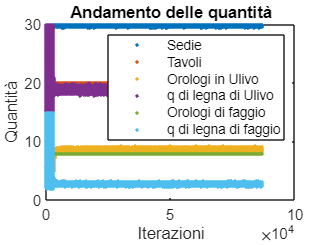


dim=length(Lb); % dimensione del problema in base ai lower bounds
T_iniziale = 100;   % temperatura iniziale
T_minima =  1e-5;  % temeratura finale
max_run=100;    % num max di runs
giri_ricerca=1000; % periodo iniziale di ricerca
k = 1;               % costante di Boltzmann
ns=0;

%contatori
run= 0; giri = 0;
% valori da settare
T = T_iniziale;
E0 = Fun(u0);
E_old = E0; E_new=E_old;
best = u0;  % setto come best i valori iniziali casuali, magari indovino

quantita=[];
quantitaAccettate=[];

% avvio ciclo
while ((T > T_minima))
    
    while 1
        if giri<giri_ricerca    % se sta ancora nel ciclo
            flag=1;
            ns=nuovaSol(u0,Lb,Ub,flag);
            quantita=[quantita ns];
        else    % setta flag 0 e vai a fare una ricerca più locale
            flag=0;
            ns=nuovaSol(best,Lb,Ub,flag);
            quantita=[quantita ns];
        end
        E_new = Fun(ns);
        if E_new<0 % soddisfa vincoli
            break;
        end
    end
    

     
      giri=giri+1; %incrementa numero giri fatti
      
    % calcola delta per sostituire (forse)
    DeltaE=E_new-E_old;
    % accettati se c'è miglioramento
    if (DeltaE <0) % se valore nuovo < vecchio
        best = ns; E_old = E_new;
        quantitaAccettate=[quantitaAccettate best];
    end 
    if (DeltaE>=0 && exp(-DeltaE/(k*T))>rand )  % se nuovo >= vecchio, sostituisci
        best = ns; E_old = E_new;
        quantitaAccettate=[quantitaAccettate best];
    else
        quantitaAccettate=[quantitaAccettate zeros(size(best))];
    end
    profitto=[profitto E_old];  % aggiorno profitto
    run = run+1;
    % controllo sul max run fatti
    if (run >= max_run)      
        run = 1;  % reset contatori
      % raffredda
        T = raffredda(alpha,T);
    end
end %fine while


figure(1)
x=1:length(quantita);
plot(x,quantita,'.');
xlabel('Iterazioni'); ylabel('Quantità');
legend('Sedie','Tavoli','Orologi in Ulivo','q di legna di Ulivo','Orologi di faggio','q di legna di faggio');
title('Andamento delle quantità');

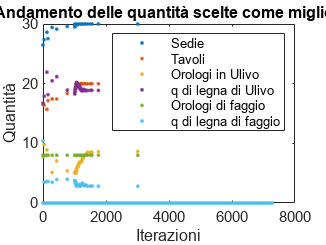

figure(2)
x=1:length(quantitaAccettate);
plot(x,quantitaAccettate,'.');
xlabel('Iterazioni'); ylabel('Quantità');
legend('Sedie','Tavoli','Orologi in Ulivo','q di legna di Ulivo','Orologi di faggio','q di legna di faggio');
title('Andamento delle quantità scelte come migliori');

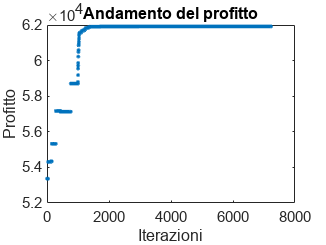

figure(3)
x=1:length(-profitto);
plot(x,-profitto,'.');  % plotta andamento del risultato nei vari tentativi
xlabel('Iterazioni'); ylabel('Profitto');
title('Andamento del profitto');

fprintf('\nQuantità da produrre:\n');


Quantità da produrre:


table(best, 'RowNames',{'Sedie';'Tavoli';'Orologi in Ulivo'; ...
    'q di Ulivo';'Orologi di Faggio';'q di Faggio'},'VariableNames',{'Quantità'})

ans = 6×1 table
                         Quantità
                         ________

    Sedie                     30 
    Tavoli                    20 
    Orologi in Ulivo      8.6496 
    q di Ulivo            18.871 
    Orologi di Faggio          8 
    q di Faggio           2.8012 


fprintf('\nProfitto: €%s', num2str(-profitto(1,end)));


Profitto: €61920.2189

fprintf('\n');
toc

Elapsed time is 38.511617 seconds.


function s=nuovaSol(u,Lb,Ub,flag) 
  % cerca in giro valora tra lb e ub
if length(Lb)>0 & flag==1   
  s=Lb+(Ub-Lb).*rand(size(u));
else
  % cerca localmente in modo random vicino al best
  s=u+0.01*(Ub-Lb).*randn(size(u));
end

s=bounds(s,Lb,Ub);
end

% raffreddamento T
function T=raffredda(alpha,T)
T=alpha*T;
end

function ns=bounds(ns,Lb,Ub)
ns_tmp=ns;  % applica lb
% vettore booleano per confronto elemento per elemento:
% se il primo elemento è min del secondo sostituisce gli elementi
% del vettore di sinistra con quello di destra
I=ns_tmp<Lb;
ns_tmp(I)=Lb(I);
J=ns_tmp>Ub;    % applica ub
ns_tmp(J)=Ub(J);
% aggiorna nuova soluzione tenendo conto dei bounds
ns=ns_tmp;
end

function z=Fun(u)
% prende la f obiettivo e fa il penalty method
z=fobj(u)+controllo(u);
end

function Z=controllo(u)
Z=0;
% costanti di penalty
lam=10^15; lameq=10^15;
[g,geq]=vincoli(u);

% vincoli di disuguaglianza
for k=1:length(g)
    Z=Z+ lam*g(k)^2*getH(g(k)); % se dis verificata, lam si annulla (moltiplicato a 0) e te ne accorgi xk esce valore 'normale'
                                %altrimenti uscirebbe valore altissimo
                                %vicino o superiore a lam
end
% vincoli di uguaglianza
for k=1:length(geq)
   Z=Z+lameq*geq(k)^2*geteqH(geq(k));
end
end


% Testa vincolo di disuguaglianza
function H=getH(g)
if g<=0
    H=0; % se è <= è verificato e dunque ritorna H=0
else
    H=1; %se <= non è verificata, restituisce un valore di f > lam fissato
end
end

% Testa vincoli di uguaglianza
function H=geteqH(g)
if g==0
    H=0;
else
    H=1; 
end
end

% funzione obiettivo
function z=fobj(u)
z= -(1000*u(1)+1500*u(2)+30*(u(4)-0.2*u(1)-0.4*u(2)-0.1*u(3))+ ...
    150*u(3)+300*u(5)+40*(u(6)-0.1*u(5))- ...
    8.5*(2*u(1)+2.5*u(2)+1.5*u(3)+3*u(4)+1.5*u(5)+3*u(6))- ...
    0.5*3*(2*u(1)+3*u(2)+3*u(4)+3*u(6)));
end

function [g,geq]=vincoli(x)
g(1)=2*x(1)+3*x(2) -120; %m2
g(2)=3*x(4)+3*x(6) -120; % m1
g(3)=+2*x(1)+2.5*x(2)+1.5*x(3) +3*x(4) + 1.5*x(5) + 3*x(6) -200; %lv (5 lavoratori per 8 ore al giorno per 5 giorni)
g(4)=+2*x(1)+4*x(2)+0.5*x(3)+1*(x(4)-0.2*x(1)-0.4*x(2) - 0.1*x(3))+0.5*x(5)+1*(x(6)-0.1*x(5)) -200; %capacità di 200 slots
g(5)=0.2*x(1)+0.4*x(2) + 0.1*x(3) -x(4) +4; % produrre almeno 4q di legna (da vendere) uliva
g(6)=0.1*x(5)-x(6) +2; % produrre almeno 2q di legna (da vendere) di faggio

% vincolo ugu
geq=[];
end